# Create a MultiLevel List From Cell Arrays

To create a multilevel list, you can nest 1-by-n cell arrays that represent the sublists in a 1-by-n cell array that represents the top-level list. Then, append the cell array that represents the top-level list to the document. For example:

import mlreportgen.dom.*;
d = Document('orderedListReport','html');

ol = {'step 1','step 2',...
     {'option 1','option 2'},...
     'step 3'};
append(d,ol);

close(d);
rptview(d);

Here is the generated  list:

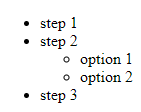

In the previous example, the generated top-level list and sublist are unordered lists. To generate either list as an ordered list, represent it as an `mlreportgen.dom.OrderedList` object. 

This example generates the sublist of the second list item as an ordered list.

import mlreportgen.dom.*;
d = Document('orderedListReport','html');

ol = {'step 1','step 2',...
     OrderedList({'option 1','option 2'}),...
     'step 3'};
append(d,ol);

close(d);
rptview(d);

Here is the generated  list:

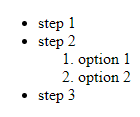

This example generates the top-level list and the sublist as an ordered list.

import mlreportgen.dom.*;
d = Document('orderedListReport','html');

ol = OrderedList({'step 1','step 2',...
     OrderedList({'option 1','option 2'}),...
     'step 3'});
append(d,ol);

close(d);
rptview(d);

Here is the generated  list:

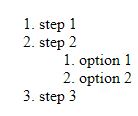

*Copyright 2019 The MathWorks, Inc.*